`Name: Maria Sabouri Dodaran`

`Student Number: 401248049`

# ***Question 2***

## **Part a**

[x, Fs] = audioread("H:\Maria\university\term_7\Maria\DSP\final_project\NoisyMusic.mp3");
x = mean(x,2);   % convert stereo to mono
N = length(x);
t = (0:N-1)/Fs;
fprintf("Sampling frequency: %.2f Hz\n", Fs);

Sampling frequency: 44100.00 Hz


### Compute DFT of signal using fft 

To analyze the noisy signal in the frequency domain, we compute its **Discrete Fourier Transform ** using an N-point FFT. The FFT output corresponds to frequency samples equally spaced between 0 and Fs.

With knowledge about relationships in domain between **countinous frequency response** and **desscrete frequency response**, the frequency axis in **Hz** is defined as:


$$f=\ \frac{k*F_s }{N}$$


X = fft(x);
f = (0:N-1)*(Fs/N);

### Plotting in countinous frequency response

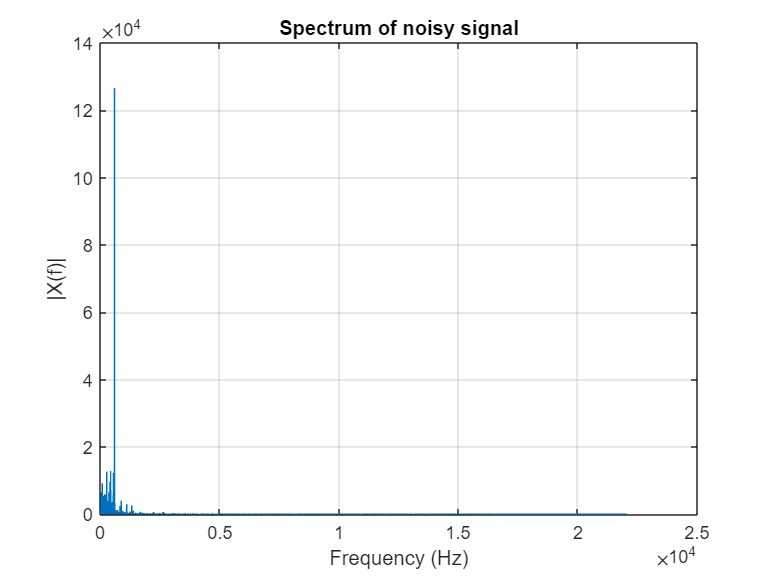

figure;
plot(f(1:floor(N/2)), abs(X(1:floor(N/2))));
grid on;
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Spectrum of noisy signal");

### Plotting in descrete frequency response

In digital signal processing it is often more convenient to represent frequency in **digital angular frequency (radians/sample)**. The relationship between analog frequency (Hz) and digital angular frequency is:


$$\omega =\ \frac{2\pi *f}{F_s }$$


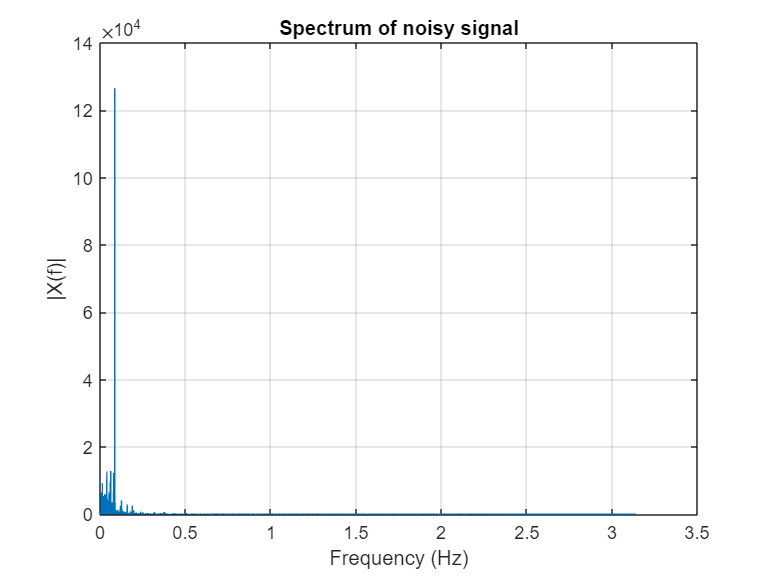

f_d = (0:N-1)*(2 * 3.1415 /N);
figure;
plot(f_d(1:floor(N/2)), abs(X(1:floor(N/2))));
grid on;
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Spectrum of noisy signal");

so now we know our filter design should filter signal at w = 0.0854828 Hz.

### Define passband and stop band

After computing the FFT of the noisy audio signal, a strong sinusoidal interference peak was detected at f_noise. To remove this narrowband noise, a bandstop (notch) filter must be designed. Therefore, a stopband region centered at the noise frequency is defined as:


$$F_{stop} =\left\lbrack f_{noise} -stop_{width} \ ,\ f_{noise} +stop_{width} \ \right\rbrack$$


Additionally, the passband edges are selected farther away from the interference frequency to preserve the useful signal content:


$$F_{pass} =\left\lbrack f_{noise} -{pass}_{width} \ ,\ f_{noise} +{pass}_{width} \ \right\rbrack$$


These frequency edges are plotted on the FFT magnitude spectrum to visually confirm the location of the noise and the selected filter boundaries.

f_noise = 600;

X_half = X(1:floor(N/2));
f_half = f(1:floor(N/2));

stop_width = 10;

Fstop1 = f_noise - stop_width;
Fstop2 = f_noise + stop_width;

pass_width = 100;

Fpass1 = f_noise - pass_width;
Fpass2 = f_noise + pass_width;

fprintf("Passband edges: %.2f Hz , %.2f Hz\n", Fpass1, Fpass2);

Passband edges: 500.00 Hz , 700.00 Hz


fprintf("Stopband edges: %.2f Hz , %.2f Hz\n", Fstop1, Fstop2);

Stopband edges: 590.00 Hz , 610.00 Hz


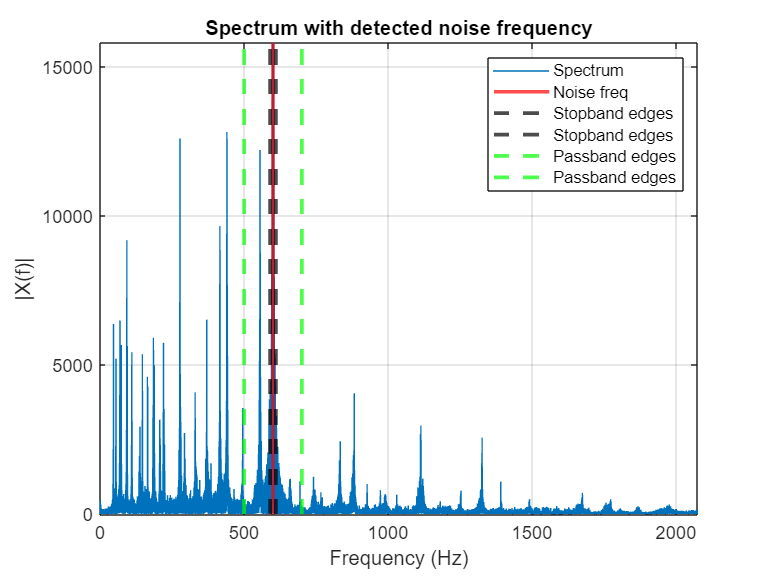

figure;
plot(f_half, abs(X_half));
grid on;
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Spectrum with detected noise frequency");

hold on;
xline(f_noise, 'r', 'LineWidth', 2);
xline(Fstop1, 'k--', 'LineWidth', 2);
xline(Fstop2, 'k--', 'LineWidth', 2);
xline(Fpass1, 'g--', 'LineWidth', 2);
xline(Fpass2, 'g--', 'LineWidth', 2);

legend("Spectrum","Noise freq","Stopband edges","Stopband edges","Passband edges","Passband edges");

### Apply IIR filters 

Fpass = [Fpass1 Fpass2];      % passband edges (Hz)
Fstop = [Fstop1 Fstop2];      % stopband edges (Hz)

Rp = 1;    % passband ripple (dB)
Rs = 50;   % stopband attenuation (dB)

Wp = Fpass/(Fs/2);   
Ws = Fstop/(Fs/2);   

#### Butterworth filter

The Butterworth filter is chosen because it has a **maximally flat frequency response** in the passband (no ripples), which makes it suitable for audio applications where signal distortion should be minimized.

- Normalize the frequencies

- Determine the minimum filter order using `buttord`

- Design the Butterworth bandstop filter

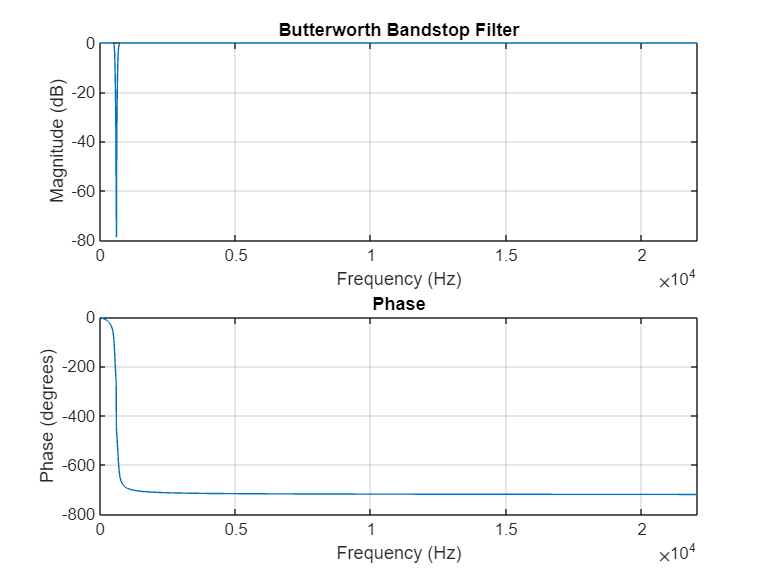

[n, Wn] = buttord(Wp, Ws, Rp, Rs);   
[b, a] = butter(n, Wn, 'stop');      
freqz(b, a, 2048, Fs);
title("Butterworth Bandstop Filter");

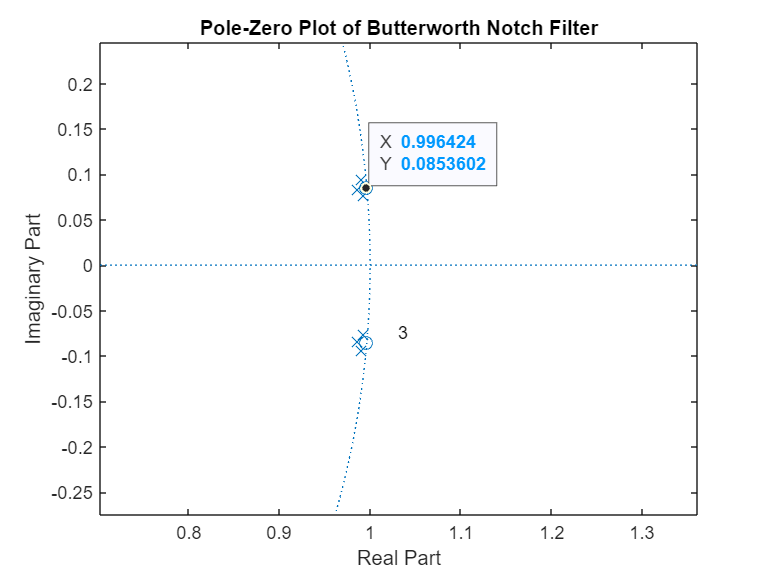

figure;
zplane(b, a);
title('Pole-Zero Plot of Butterworth Notch Filter');

y = filter(b, a, x);
% sound(y, Fs);

As we can see zerp response in at :


$$\omega =\tan^{-1} \frac{0.0853543}{0.996436}=0.0854410$$


**Refrences:**

[https://www.mathworks.com/help/signal/ref/buttord.html](https://www.mathworks.com/help/signal/ref/buttord.html)

[https://www.mathworks.com/help/signal/ref/butter.html](https://www.mathworks.com/help/signal/ref/butter.html)

#### Elliptic filter

Elliptic filters are well-known for providing the **sharpest transition band** compared to Butterworth and Chebyshev filters. This means they can achieve a narrow and deep notch with a **lower filter order**, which makes them very efficient.

However, elliptic filters introduce ripples in both the passband and stopband.

- Determine the minimum filter order using **ellipord**

- Design the elliptic bandstop filter using **ellip**

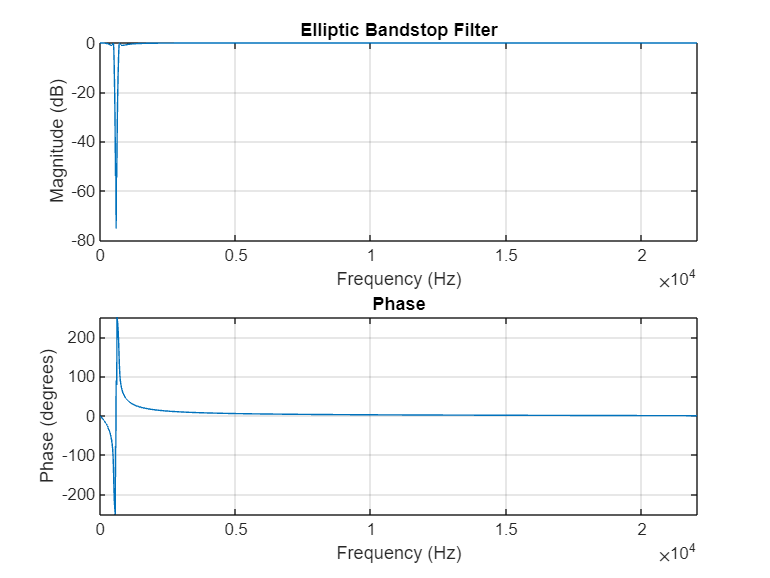

[n,Wp] = ellipord(Wp,Ws,Rp,Rs);
[b,a] = ellip(n,Rp,Rs,Wp,'stop');
freqz(b, a, 2048, Fs);
title("Elliptic Bandstop Filter");

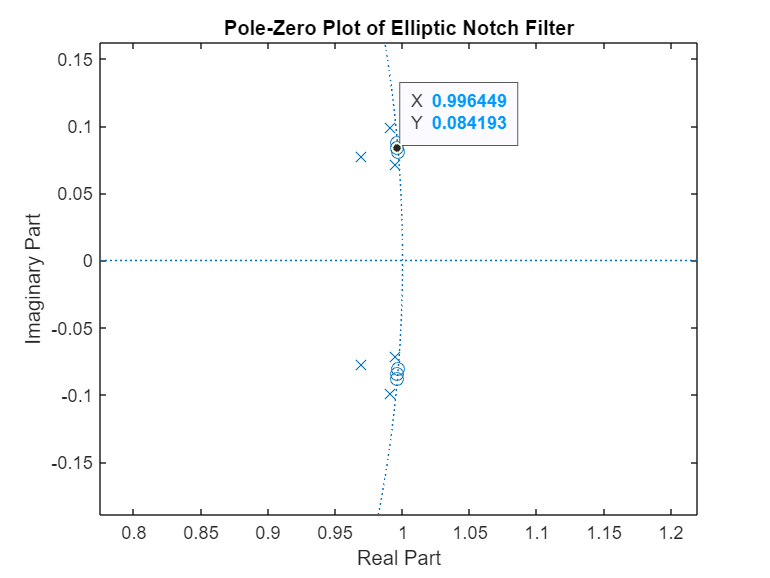

figure;
zplane(b, a);
title('Pole-Zero Plot of Elliptic Notch Filter');

y = filter(b, a, x);
sound(y, Fs);

As we can see zerp response in at :


$$\omega =\tan^{-1} \frac{0.084193}{0.996449}=0.0842928$$


**Refrences:**

[https://www.mathworks.com/help/signal/ref/ellip.html](https://www.mathworks.com/help/signal/ref/ellip.html)

[https://www.mathworks.com/help/signal/ref/ellipord.html](https://www.mathworks.com/help/signal/ref/ellipord.html)

### Apply FIR filters 

To remove the noise component at f0=600 Hz, an FIR bandstop (notch) filter is designed using the **Kaiser window method**. The Kaiser method is widely used because it allows us to control:

- **Stopband attenuation** (how deep the notch is)

- **Transition width** (how sharp the notch is)

here's steps for having this filter:

- Define the notch center frequency

- Define required stopband attenuation

- Define the transition width

- Compute stopband edge frequencies

- Normalize cutoff frequencies

- Compute Kaiser window beta parameter

- Convert transition width to radians/sample

f0 = 600; 

A = 70;           % Stopband attenuation (dB)
delta_f = 120;     % transition width (Hz) (choose 10-30 based on your needs)

f1 = f0 - delta_f / 2;   
f2 = f0 + delta_f / 2;   

Wn = [f1 f2]/(Fs/2);

if A > 50
    beta = 0.1102*(A - 8.7);
elseif A >= 21
    beta = 0.5842*(A - 21)^0.4 + 0.07886*(A - 21);
else
    beta = 0;
end

Delta_w = 2*pi*(delta_f/Fs); 

N = ceil((A - 8) / (2.285*Delta_w));
if mod(N,2)==1
    N = N + 1; 
end

fprintf("Estimated FIR order = %d\n", N);

Estimated FIR order = 1588


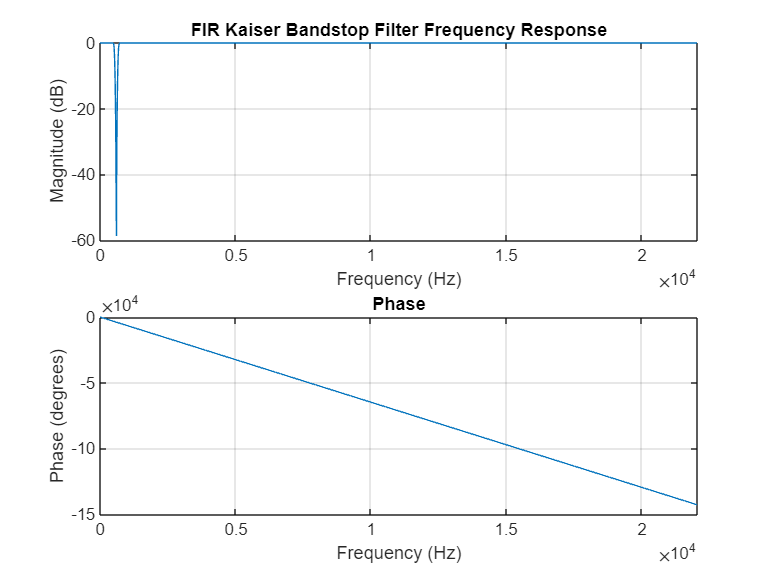


b = fir1(N, Wn, "stop", kaiser(N+1, beta));

figure;
freqz(b, 1, 2048, Fs);
title("FIR Kaiser Bandstop Filter Frequency Response");

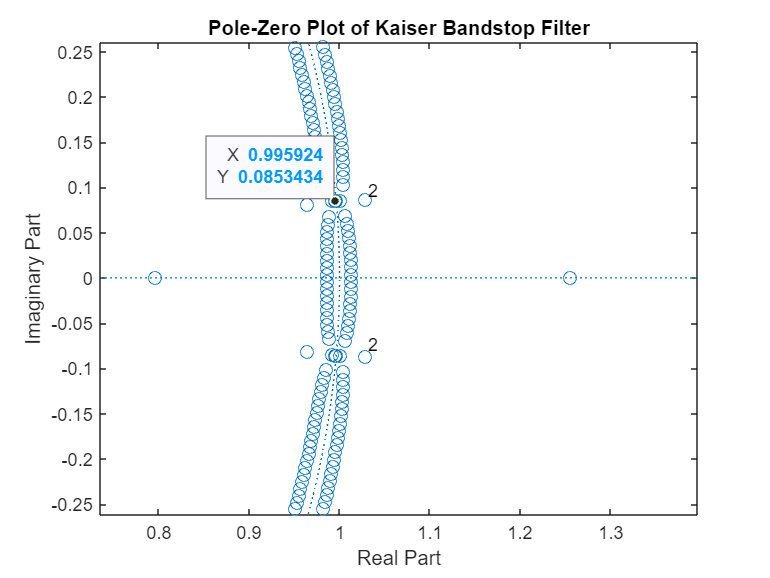

figure;
zplane(b, 1);
title('Pole-Zero Plot of Kaiser Bandstop Filter');

y = filter(b, 1, x);
% sound(y, Fs);

As we can see zerp response in at :


$$\omega =\tan^{-1} \frac{0.0853434}{0.995924}=0.0854838$$


**Refrences:**

[https://www.mathworks.com/help/signal/ref/kaiser.html#d126e137276](https://www.mathworks.com/help/signal/ref/kaiser.html#d126e137276)

[https://www.mathworks.com/help/signal/ref/fir1.html#bulla52-Wn](https://www.mathworks.com/help/signal/ref/fir1.html#bulla52-Wn)

## **Part b**

- **In the time domain:** Estimating the noise frequency is usually difficult and not very accurate, unless the noise is very strong and clearly sinusoidal.

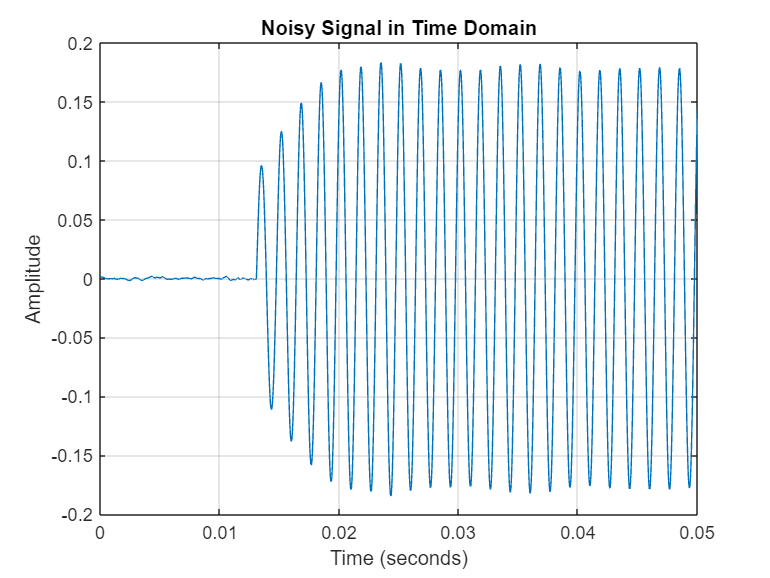

figure;
plot(t, x);
xlim([0 0.05]);
grid on;
xlabel("Time (seconds)");
ylabel("Amplitude");
title("Noisy Signal in Time Domain");

- **In the frequency domain (FFT):** Estimating the noise frequency is very easy and accurate because sinusoidal noise appears as a clear peak in the spectrum.

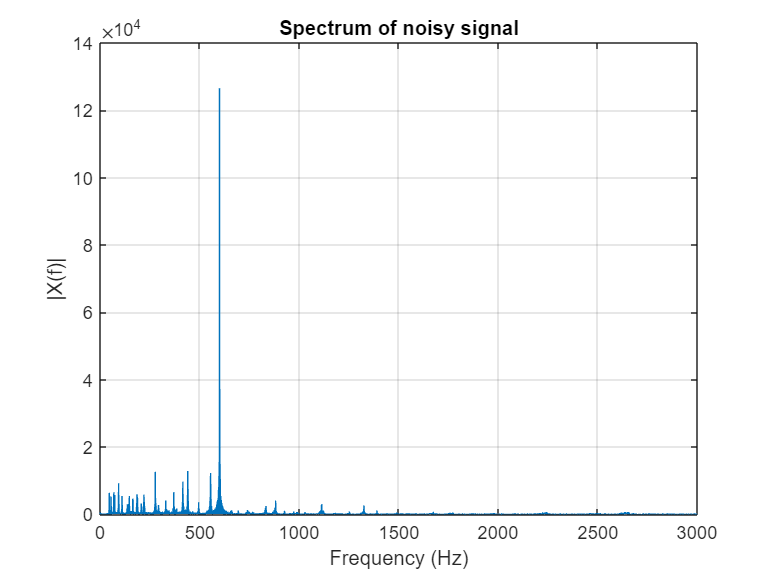

figure;
N = length(x);
plot(f(1:floor(N/2)), abs(X(1:floor(N/2))));
grid on;
xlim([0 3000])
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Spectrum of noisy signal");